# **Non-Parametric Volatility Estimation**

In this example we obtain a non-parametric volatility estimate for each commodity series using an exponentially-weighted moving average (EWMA).

The procedure for estimating the underlying volatility of a time series using an EWMA model is described below. 

Let$$\{r_n\}$$denote the sequence of commodity returns and let$$\{y_n\}$$ be the sequence of EWMA estimates for the instantaneous variance. The difference equation for computing the sequence $\{y_n\}$ is as follows.


$$y_1 =r_1^2 ,\;\;\;\;\;\;\;\;\;\;y_n =\lambda y_{n-1} +\left(1-\lambda \right)r_n^2 ,\;\;\;\;\;\;\;\;\lambda \in \;\left\lbrack 0,1\right\rbrack ,\;\;\;\;\;n\ge 2$$


- Here, $$\lambda$
$ is a scalar smoothing parameter chosen from the interval $$[0, 1]$$. 

- In many typical applications, $0.90\leq \lambda\leq 0.99$, and in our example we take $\lambda = 0.94$.

- As $\lambda$ increases, the influence of the previous moving average estimate ($y_{n-1}$) on the current variance estimate ($y_n$) increases and the influence of the current squared return ($r_n^2$) decreases. 

- If $\lambda$ is close to 1, then the influence of the current squared return value $r_n^2$ is negligible in the moving average and $y_{n-1}$ dominates. If $\lambda$ is close to 0, then the current squared return value $r_n^2$ dominates and $y_{n-1}$ is negligible.

Note that we use the *square* of the commodity returns in the EWMA computation. This is because we estimate the instantaneous *variance* of the portfolio return series, from which we will take the square root to obtain estimates for the instantaneous *volatility* (standard deviation).

*Copyright 2022-2023 The MathWorks, Inc.*

## Load the commodity data.

load( "Commodities.mat" )
commodityNames = string( Returns.Properties.VariableNames );

## Compute the exponentially-weighted moving averages.

Define the smoothing parameter $\lambda$.

lambda = 0.94;

Standard form for a filter in MATLAB is the following:


$$a_0y_n = b_0x_n+b_1x_{n-1}+\dots +b_kx_{n-k} - a_1y_{n-1}-\dots -a_{n-\ell}y_{n-\ell}$$


where $\mathbf{a}=[a_0, a_1, a_2, a_{n-\ell}]$ and $\mathbf{b}=[b_0, b_1, \dots, b_k]$ are the filter coefficients. See the [`filter`](https://www.mathworks.com/help/matlab/ref/filter.html) function for further details.

Write down the EWMA filter coefficients in standard form as follows:


$$ 1 y_n + (-\lambda)y_{n-1} = (1-\lambda)r_n^2$$


Here, we have $\mathbf{a}=[1, -\lambda]$ and $\mathbf{b}=[1-\lambda]=1-\lambda$.

a = [1, -lambda];
b = 1 - lambda;

Compute the instantaneous variance and volatility estimates.

instantVariance = filter(b, a, Returns.Variables.^2);
InferredVolatility = sqrt( instantVariance );

Create a timetable containing the estimated volatilities.

InferredVolatility = array2timetable( InferredVolatility, ...
    "VariableNames", commodityNames, ...
    "RowTimes", Returns.Date );
InferredVolatility.Properties.DimensionNames(1) = "Date";

## Visualize the estimated volatility series.

Select one of the commodities and visualize its price series, its return series, and the inferred volatility.

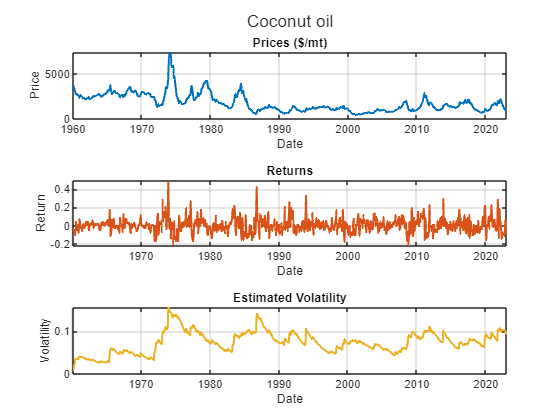

chosenCommodity = commodityNames(8);

figure
tiledlayout( 3, 1 )
sgtitle( chosenCommodity )
corder = colororder();

nexttile
plot( Prices.Date, Prices.(chosenCommodity), ...
    "LineWidth", 1.5, "Color", corder(1, :) )
xlabel( "Date" )
ylabel( "Price" )
units = Prices.Properties.VariableUnits(chosenCommodity);
title( "Prices " + units )
grid on

nexttile
plot( Returns.Date, Returns.(chosenCommodity), ...
    "LineWidth", 1.5, "Color", corder(2, :) )
xlabel( "Date" )
ylabel( "Return" )
title( "Returns" )
grid on

nexttile
plot( InferredVolatility.Date, InferredVolatility.(chosenCommodity), ...
    "LineWidth", 1.5, "Color", corder(3, :) )
xlabel( "Date" )
ylabel( "Volatility" )
title( "Estimated Volatility" )
grid on

## Use the estimated volatility to perform factor analysis on the commodities.

In this section we apply factor analysis as another technique for grouping the commodities into clusters, based on the estimated volatility profiles.

Factor analysis assumes the existence of a certain number of hidden, or latent, factors underlying the data. If we hypothesize that the volatility in the commodities is driven by a smaller number of latent factors (such as external market conditions) then factor analysis provides one approach for understanding these hidden factors.

See the function [`factoran`](matlab: doc factoran) for more details on factor analysis.

numLatentFactors = 3;
loadings = factoran( InferredVolatility.Variables, numLatentFactors );

Visualize the factor loadings.

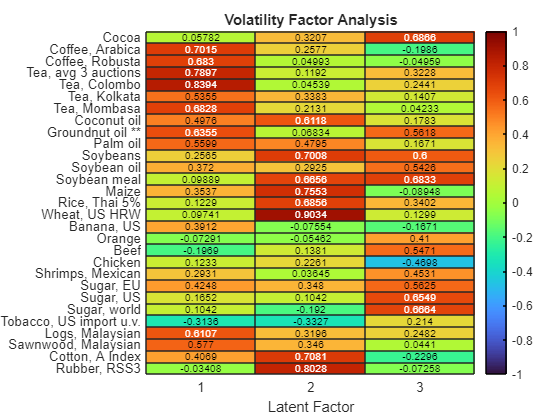

figure
heatmap( 1:numLatentFactors, commodityNames, loadings, ...
    "Colormap", turbo, ...
    "ColorLimits", [-1, 1] )
xlabel( "Latent Factor" )
title( "Volatility Factor Analysis" )

Visualize the strongest assocation with each latent factor for each factor.

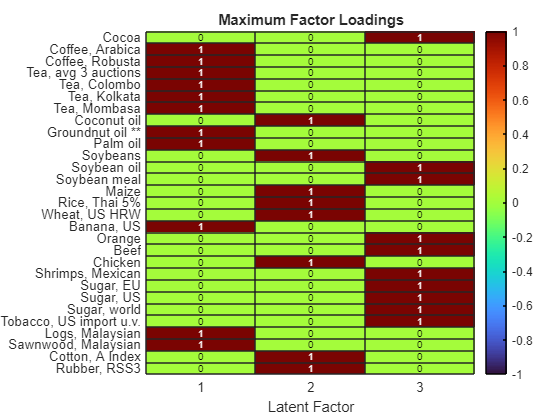

maxIdx = double( loadings == max( loadings, [], 2 ) );
figure
heatmap( 1:numLatentFactors, commodityNames, maxIdx, ...
    "Colormap", turbo, ...
    "ColorLimits", [-1, 1] )
xlabel( "Latent Factor" )
title( "Maximum Factor Loadings" )

We see that coffee, tea, groundnut oil, palm oil, bananas, and wood have a strong association with latent factor 1. 

Coconut oil, soybeans, maize, rice, wheat, chicken, cotton, and rubber have a strong association with latent factor 2.

Latent factor 3 is associated with cocoa, soybean oil, soybean meal, oranges, beef, shrimps, sugar, and tobacco.

The strongest negative association in the loadings matrix is chicken with latent factor 3. Other loadings for chicken are relatively low, indicating that chicken volatility is an outlier in this data set, as we can also observe using other methods.

## Save the inferred volatility for later use.

save( "Commodities.mat", "InferredVolatility", "-append" )